### POSTURE VALIDATION

## Initialization

clear 
close all
clc


set_param('full_system', "FastRestart", "off");


## Parameters Setting

% Model Parameters

% Posture regulation strategy filename            
% Available options for easy testing:
posture = 'posture_subsys'; 
% posture = 'caertesian_subsys';

% Trajectory tracking strategy filename
% Available options for easy testing:
% trajectory = 'feed_lin_sagittal_sub';
% trajectory = 'feed_lin_double_deriv_sub';
% trajectory = 'trajectory_tracking_linear_sub';
 trajectory = 'trajectory_tracking_non_linear_sub'; 


distance_threshold = 4;                 % Distance threshold for control strategy switch

% Controller Gains

sagittal_K = [10; 5];                   % Sagittal Axis Controller Gain

double_deriv_Kp = [2 0; 0 5];           % Double Derivative Controller Gains
double_deriv_Kd = [5 0; 0 5];

csi = 1/sqrt(2);                        % (Non)Linear Trajectory Tracking Dampening Factor
a = 5;                                  % " Gain

b = 2;                                  % " Gain


% Test Parameters

N = 150;                                % Number of test runs for validation


% !!! need clarification !!!
delta = 0.01*pi;
results = zeros(N,5);

## Model Control Strategy Setting

% vvv DON'T CHANGE THIS CODE IF YOU DON'T KNOW WHAT YOU ARE DOING !!! vvv

set_param('full_system', "FastRestart", "off");

% Change the posture regulation strategy
set_param('full_system/Agent 1/PR', 'ReferencedSubsystem', posture);

% Change the trajectory tracking strategy
set_param('full_system/Agent 1/TT', 'ReferencedSubsystem', trajectory);

% Save model
 save_system('full_system', 'SaveDirtyReferencedModels', 'on')

% ^^^ --------------------------------------------------------------- ^^^


## Model Validation Through Random Initial Condition Generation

check_convergence = 1

errors =     0.3361    0.2876    0.3370


check_convergence = 1

errors =     0.3072    0.3698    0.4968


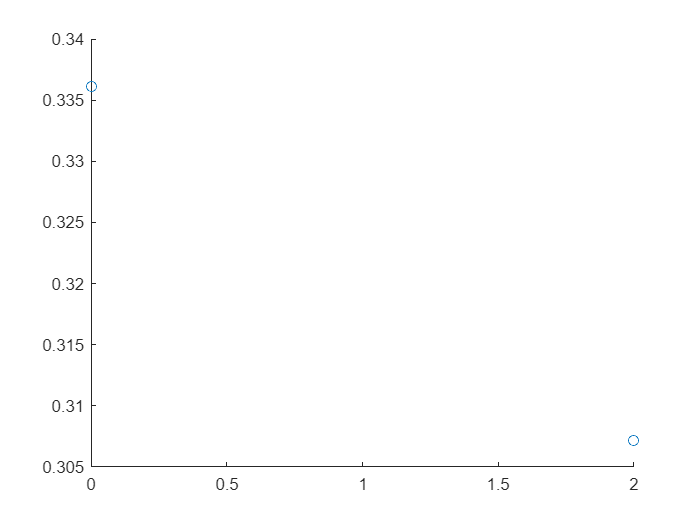

w = warning('off','all');
set_param('full_system', "FastRestart","on");

for i=1:N
    initial_conditions_1 = [randi([-11 11],1,2) , (2*pi - delta)*rand(1,1)];
    initial_conditions_2 = [randi([-11 11],1,2) , (2*pi - delta)*rand(1,1)];
    initial_conditions_3 = [randi([-11 11],1,2) , (2*pi - delta)*rand(1,1)];
    

    initial_conditions_trans_1 = state_transformation([0,0,0], initial_conditions_1);
    initial_conditions_trans_2 = state_transformation([0,0,0], initial_conditions_2);
    initial_conditions_trans_3 = state_transformation([0,0,0], initial_conditions_3);

    out = sim('full_system', "StopTime", "10");
    warning(w);
    time_sim = out.data.time;
    check_convergence = out.check.signals.values(end,1);
    convs = out.errors.signals(2).values;
    tau = find(convs, 1, 'first');
    conv_time = time_sim(tau);
    errors = [0 0 0];

    if (check_convergence)
        errors = out.errors.signals(1).values(tau, :);
    end
    
    results(i,:) = [errors check_convergence conv_time];
end

set_param('full_system', "FastRestart", "off");


ANALYSIS

total_error = 0;
conv_time_mean = 0;
for i=1:N
    check_convergence = results(i,4);
    if (check_convergence)
        total_error = total_error + sum(results(i,1:3));
        conv_time_mean = conv_time_mean + results(i,5);
    end
end

conv_time_mean = 4.9000

conv_time_mean = 8.7000


total_error = total_error / N

total_error = 1.0672

conv_time_mean  = conv_time_mean / N

conv_time_mean = 4.3500

function circle(x,y,r)
%x and y are the coordinates of the center of the circle
%r is the radius of the circle
%0.01 is the angle step, bigger values will draw the circle faster but
%you might notice imperfections (not very smooth)
ang=0:0.01:2*pi; 
xp=r*cos(ang);
yp=r*sin(ang);
plot(x+xp,y+yp, LineWidth=0.7, Color='k');
end